Logic:

People may not have "internalized" the impact of sample size on the precision of correlation estimates, and the consequences of small effect sizes on sample size requirements for powered studies.

Likewise, they may not have internalized even after reading Marek et al. and other work the impact of multivariate analyses and choices that yield larger effect sizes on power.

For example, an average effect size of r = 0.4 for multivariate analyses vs. 0.1 for univariate analyses is only a difference of 0.3. But the impact on sample size and power is enormous: A 16-fold difference in sample size requirements.

Marek et al. 2022 compare multivariate and univariate effect sizes (averaging effect sizes over the top 1% of univariate features).

Multivariate analyses show correlations on average about 4x larger than univariate effect sizes.

We can translate that difference into a difference in variance explained, power for a given sample size, and critical sample size needed.

mv = 0.4; % correlation
uv = 0.1; % correlation

var_ratio = 0.4^2 ./ (0.1^2)

var_ratio = 16

 Variance explained ratios are based on r^2. They are 16 times larger for multivariate analyses.

Power curves and sample size 

% Plot power curves
create_figure('Power')
[ncritmv,pow,obspowmv] = power_calc(mv, .001, 200, 'r', [1 0 0], 0, 1);

One sample: d = 0.87, N needed 80% =  88 , N needed 50% =  58

2-group: d = 0.87, N per group 80% = 169 , N per group 50% = 108



[ncrituv,pow,obspowuv] = power_calc(uv, .001, 200, 'r', [.3 .7 1], 0, 1);

One sample: d = 0.20, N needed 80% = 1537 , N needed 50% = 953

2-group: d = 0.20, N per group 80% = Inf , N per group 50% = 1899



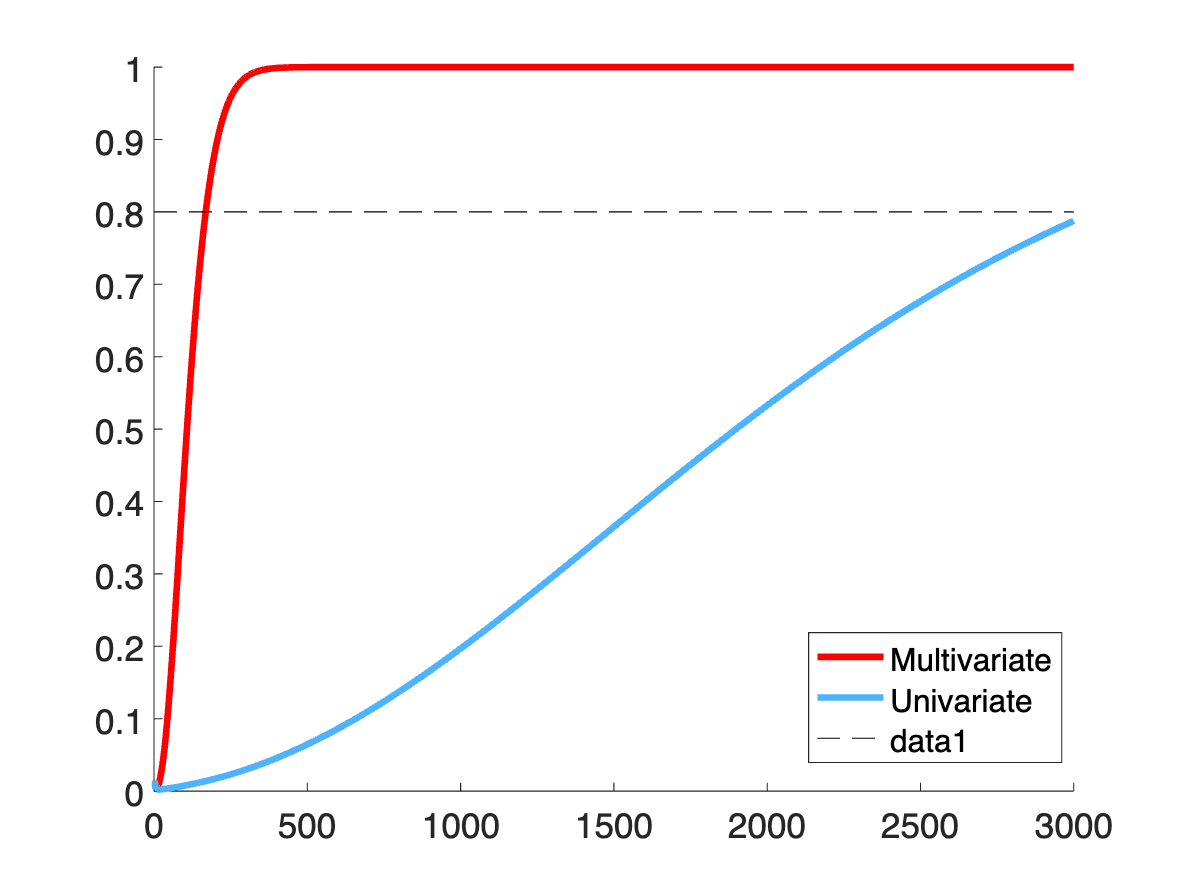


legend({'Multivariate' 'Univariate'})
hh = plot_horizontal_line(0.8); set(hh, 'LineStyle', '--');
ylabel('Power')
legend({'Multivariate' 'Univariate' '80% Power'})
legend("Position", [0.66952,0.13394,0.2376,0.16253])


set(gca, 'FontSize', 24)
xlabel('Sample size');

ncrituv./ncritmv


The number needed for 80% power for one-sample association detection is n = 88 for multivariate, and n = 1537 for univariate. 

n_for_80_percent_power_ratio = ncrituv/ncritmv

n_for_80_percent_power_ratio = Inf

We need about 17 times as many participants for univariate tests.

obspowmv

obspowmv = 0.9985

obspowuv

obspowuv = 0.0437

With n = 200 as an arbitrary sample size, power with multivariate analysis is 99%, and power with univariate analysis is 4.4%.

### Let's make another plot with data from marek fig4f

SVR vs Univ, resting-state fMRI, 41 phenotypes in ABCD

mv_vs_uv = [    0.1505    0.0593
0.1831    0.0529
0.2557    0.0752
0.1907    0.0381
0.0597    0.0506
0.2329    0.0707
0.3387    0.0955
0.0596    0.0473
0.2206    0.0666
0.1739    0.0628
0.1193    0.0530
0.1422    0.0605
0.3199    0.0725
0.2495    0.0713
0.3852    0.0917
0.1139    0.0919
0.2836    0.0801
0.0320    0.0474
0.1139    0.0511
0.0166    0.0447
0.0885    0.0507
0.0466    0.0437
0.0609    0.0506
0.0617    0.0470
0.1419    0.0554
0.1286    0.0638
0.1040    0.0555
0.0969    0.0456
0.1316    0.0543
0.1363    0.0516
0.1687    0.0656
0.1628    0.0645
0.0416    0.0425
0.1015    0.0497
0.1024    0.0635
0.0742    0.0474
0.0593    0.0488
0.1107    0.0657
0.0677    0.0454
0.0648    0.0456
0.0732    0.0485];

mx = max(mv_vs_uv);
md = median(mv_vs_uv);


% Plot power curves
create_figure('Power')

ans =   Figure (Power) with properties:

      Number: 11
        Name: 'Power'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


colors = seaborn_colors(6);
[ncritmv,pow,obspowmv] = power_calc(mx(1), .001, 200, 'r', colors{6}, 0, 1);

One sample: d = 0.83, N needed 80% =  95 , N needed 50% =  62



[ncritmv,pow,obspowmv] = power_calc(prctile(x(:, 1), 75), .001, 200, 'r', colors{6}/1.5, 0, 1);

One sample: d = 0.36, N needed 80% = 489 , N needed 50% = 306



[ncrituv,pow,obspowuv] = power_calc(md(1), .001, 200, 'r', colors{6}/2, 0, 1);

One sample: d = 0.23, N needed 80% = 1183 , N needed 50% = 734



[ncrituv,pow,obspowuv] = power_calc(mx(2), .001, 200, 'r', colors{5}, 0, 1);

One sample: d = 0.19, N needed 80% = 1686 , N needed 50% = 1045



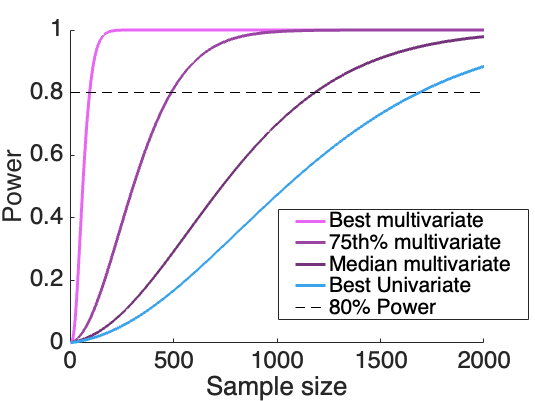


legend({'Best multivariate' '75th% multivariate' 'Median multivariate' 'Best Univariate'})
hh = plot_horizontal_line(0.8); set(hh, 'LineStyle', '--');
ylabel('Power')
legend({'Best multivariate' '75th% multivariate' 'Median multivariate' 'Best Univariate' '80% Power'})
legend("Position", [0.52165,0.19637,0.44804,0.28601])

set(gca, 'FontSize', 24, 'XLim', [0 2000])
xlabel('Sample size');

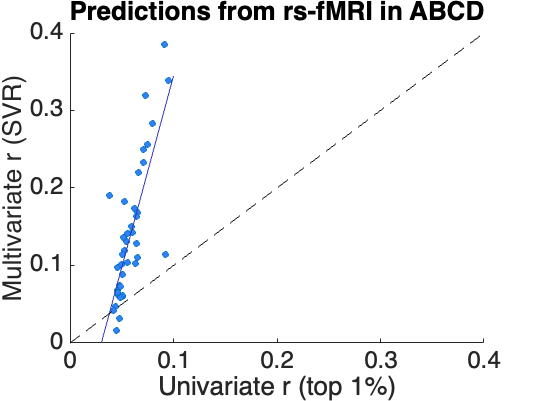

% this is data x above in table form
% marekt = readtable('Marek_Supplementary_Table_1_ABCD_measures.tsv', 'FileType', 'text', 'Delimiter', '\t')
% fig4f = readtable('Marek_Fig04_Source_Data_41586_2022_4492_MOESM7_ESM.xlsx', "Sheet", "Panel f")

create_figure('scatter'); 
plot(fig4f.x99_Univariate, fig4f.SVRRpred, 'o', 'MarkerFaceColor', [.2 .5 1]);
xlabel('Univariate r (top 1%)'); ylabel('Multivariate r (SVR)'); title('Predictions from rs-fMRI in ABCD');
hh = refline; set(hh, 'Color', [.2 .2 .7]);
set(gca, 'FontSize', 24);
set(gca, 'XLim', [0 .4], 'YLim', [0 .4])
h3 = plot([0 .4], [0 .4], '--');
set(h3, 'Color', 'k');

## Plot power curves at p < 0.05


create_figure('Power')

ans =   Figure (Power) with properties:

      Number: 22
        Name: 'Power'
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


pthr = 0.025;
colors = seaborn_colors(6);
[ncritmv,pow,obspowmv] = power_calc(mx(1), pthr, 200, 'r', colors{6}, 0, 1);

One sample: d = 0.83, N needed 80% =  49 , N needed 50% =  27



[ncritmv,pow,obspowmv] = power_calc(prctile(x(:, 1), 75), pthr, 200, 'r', colors{6}/1.5, 0, 1);

One sample: d = 0.36, N needed 80% = 249 , N needed 50% = 125



[ncrituv,pow,obspowuv] = power_calc(md(1), pthr, 200, 'r', colors{6}/2, 0, 1);

One sample: d = 0.23, N needed 80% = 602 , N needed 50% = 297



[ncrituv,pow,obspowuv] = power_calc(mx(2), pthr, 200, 'r', colors{5}, 0, 1);

One sample: d = 0.19, N needed 80% = 857 , N needed 50% = 422



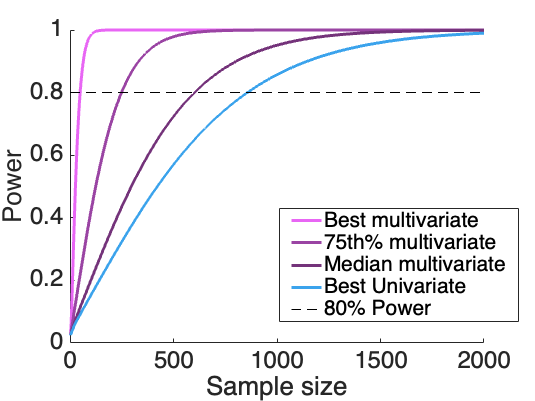


legend({'Best multivariate' '75th% multivariate' 'Median multivariate' 'Best Univariate'})
hh = plot_horizontal_line(0.8); set(hh, 'LineStyle', '--');
ylabel('Power')
legend({'Best multivariate' '75th% multivariate' 'Median multivariate' 'Best Univariate' '80% Power'})
legend("Position", [0.52165,0.19637,0.44804,0.28601])

set(gca, 'FontSize', 24, 'XLim', [0 2000])
xlabel('Sample size');